# Analisi progetti INTEGRAZIONE rispetto al settore 

close all
clear all
clc
tProgetto = readtable('progetti_settaccio_INTEG.xlsx');
% trasformo in categorical array per lavorarci su 
tProgetto.CUP_DESCR_SETTORE = categorical(tProgetto.CUP_DESCR_SETTORE);


## Quanti progetti per settore?

Valutiamo il numero dei progetti per settore. Il settore con più progetti sull'Integrazione è ..........

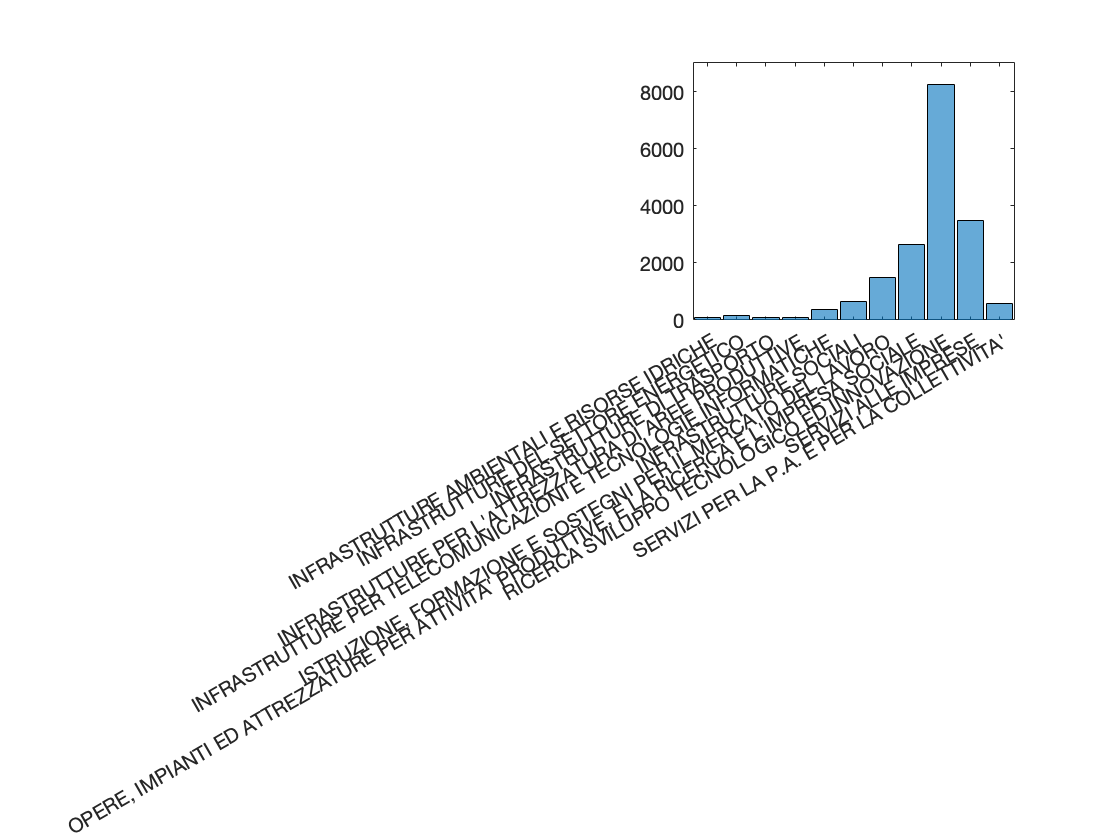

% quanti progetti per settore? 
histogram(tProgetto.CUP_DESCR_SETTORE);

## Settori più finanziati 

Valutiamo adesso i primi 10 progetti più finanziati a quali settori appartengono.

Quali sono i 10 progetti più finanziati? Realizzare una tabella con progetti, settore e finanziamento 

N = 10;
tProgetto = sortrows(tProgetto,'FINANZ_TOTALE_PUBBLICO','descend');
topN = tProgetto(1:N,["COD_LOCALE_PROGETTO","CUP_DESCR_SETTORE","FINANZ_TOTALE_PUBBLICO"])

topN = 10×3 table
    COD_LOCALE_PROGETTO    CUP_DESCR_SETTORE    FINANZ_TOTALE_PUBBLICO
    ___________________    _________________    ______________________

        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          
        {0×0 char}            <undefined>                NaN          


##  Distrubuzione dei finanziamenti per settore 

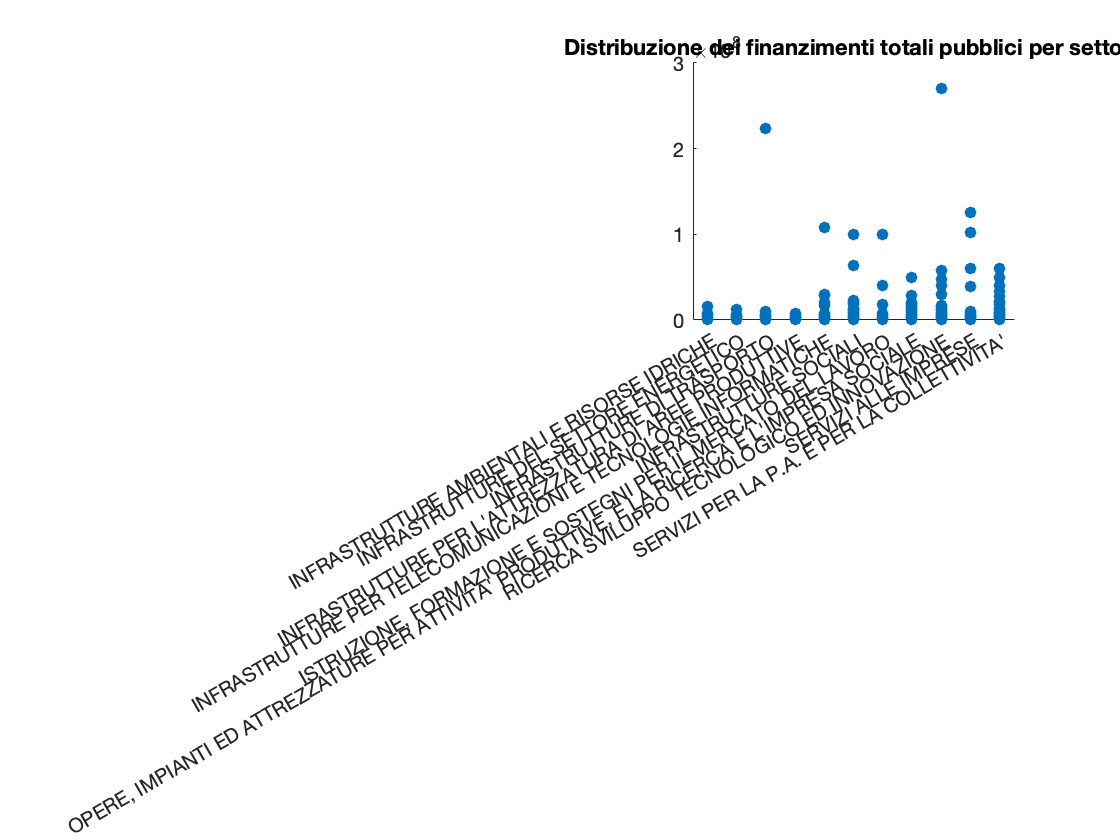

tSettoreFinanze = tProgetto(:,["CUP_DESCR_SETTORE","FINANZ_TOTALE_PUBBLICO"]);
x=tSettoreFinanze.CUP_DESCR_SETTORE;
y=tSettoreFinanze.FINANZ_TOTALE_PUBBLICO;
scatter(x,y,'filled')
title('Distribuzione dei finanzimenti totali pubblici per settore')

## Somma dei finanziamenti totali pubblici per ogni settore dal 2014 al 2020

Quali sono stati i finanziamenti totali per ogni settore?  Qual è il settore che ha avuto il massimo dei finanziamenti? 

settori = unique(tSettoreFinanze.CUP_DESCR_SETTORE,'stable');
tSettoreFinanze = sortrows(tSettoreFinanze,'CUP_DESCR_SETTORE','ascend');
dim = length(settori);
FinanzimentoTOT = zeros(1,dim);

for i=1:dim
    FinanzimentoTOT(i) = sum(tSettoreFinanze.FINANZ_TOTALE_PUBBLICO(tSettoreFinanze.CUP_DESCR_SETTORE == settori(i)));
end



tFinanzeTot = table(settori,FinanzimentoTOT');
bar(tFinanzeTot.settori,tFinanzeTot.Var2,'DisplayName','tFinanzeTot.Var2')
title('Somma dei finanzimenti totali pubblici dal 2014 al 2020')


Il settore che ha ricevuto più finanzimenti nel corso degli anni dal 2014 al 2020 è  ............. con un totale di .... progetti.